# PARCIAL TERCER CORTE.

## Segundo punto.

Control lineal.

Ingresa funcion de transferencia.

% Definir la función de transferencia
num = [5 707.3];   % Coeficientes del numerador
den = [1 132.5 1273];   % Coeficientes del denominador
sys = tf(num, den)   % Crear la función de transferencia

sys =
 
      5 s + 707.3
  --------------------
  s^2 + 132.5 s + 1273
 
Continuous-time transfer function.
Model Properties


Espacios de estado.

% Obtener la representación en espacio de estados
sys_ss = ss(sys);

% Obtener las matrices de estado
A = sys_ss.A;   % Matriz de estado A
B = sys_ss.B;   % Matriz de entrada B
C = sys_ss.C;   % Matriz de salida C
D = sys_ss.D;   % Matriz de transmisión directa D

% Imprimir las matrices de estado
disp('Matriz de estado A:');

Matriz de estado A:


disp(A);

 -132.5000  -39.7812
   32.0000         0



disp('Matriz de entrada B:');

Matriz de entrada B:


disp(B);

     4
     0



disp('Matriz de salida C:');

Matriz de salida C:


disp(C);

    1.2500    5.5258



disp('Matriz de transmisión directa D:');

Matriz de transmisión directa D:


disp(D);

     0



Controlabilidad y observabilidad.

% Verificar controlabilidad
controllability = rank(ctrb(A, B));
if controllability == min(size(A))
    disp('El sistema es controlable.');
else
    disp('El sistema no es completamente controlable.');
end

El sistema es controlable.



% Verificar observabilidad
observability = rank(obsv(A, C));
if observability == min(size(A))
    disp('El sistema es observable.');
else
    disp('El sistema no es completamente observable.');
end

El sistema es observable.


Graficas.

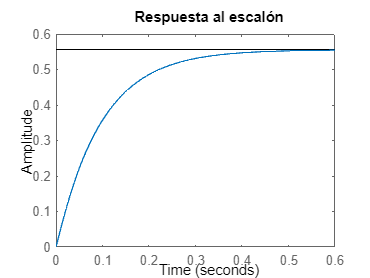

% Graficar la respuesta al escalón
figure;
step(sys);
title('Respuesta al escalón');

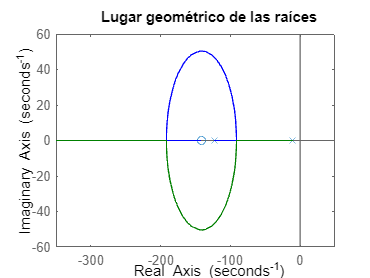


% Graficar el lugar geométrico de las raíces
figure;
rlocus(sys);
title('Lugar geométrico de las raíces');

Primer punto.

Compensador por adelanto y atraso.

A=[-132.55 39.78; 32 0]

A =  -132.5500   39.7800
   32.0000         0


B=[4; 0]

B =      4
     0


C=[1.25 0]

C =     1.2500         0


D=[0]

D = 0

%Espacio de Estados del sistema
sys=ss(A,B,C,D);
[a,b]=ss2tf(A,B,C,D)

a =      0     5     0


b = 1.0e+03 *

    0.0010    0.1326   -1.2730


%escoges el ultimo coeficiente de cada vector de la funcion de tranferencia para ña gancia del compensador
K=20/(a(1,4)/b(1,4))

Index in position 2 exceeds array bounds. Index must not exceed 3.

G=tf(a,b)9
A=tf(1,[1 0])% 1/s
F=(K*G*A)
figure
step(G)
figure
step(F)
figure
margin(F)
%%Diseño
Wm=24 %frecuencia de diseño la misma del margen de fase o un poquitico la derecha o izq

FaseWm=-250 %Fase de frecuacia de diseño UNIDADES (GRADOS)

mf=70a%margen de fase de diseño (PM) o la varias dependiendo los valores de alpha y beta

Madc=5%phiadicionadi lo dejas igual
M=abs(13.3)%Magnitud de fase (DB) a la frecuacuai que escogiste
%%
phi=-180-(FaseWm)+mf+Madc
    alpha=(1-sind(phi))/(1+sind(phi))
    syms B
    Beta=solve(20*log10(B)==M-10*log10(alpha),B)
    BB=double(Beta)
%%REVISA SUPER BIEN LOS VALORES ANTES DE TENER EL COMPENSADOR

%%
%EL RESTO SALE SOLO
    %Compensador de adelanto
    %1/t1=Wmsqrt(alpha) Zero
    zeroAD=Wm*sqrt(alpha)
    %polo
    T1=1/zeroAD
    poloAD=1/(T1*alpha)
    %%Compensador de atraso
    %1/t2=Wm/10 Zero
    zeroAT=Wm/10
    T2=1/zeroAT
    poloAT=round(1/(T2*BB),4)
    anguloN=atand(zeroAT)-atand(Wm/poloAT)
    GAT=tf([1 zeroAT],[1 poloAT])
    GAD=tf([1 zeroAD],[1 poloAD])
    Gc=((1/alpha)*GAD)*((1/BB)*GAT)
    GG=Gc*F
    H=feedback(GG,1)
figure
hold on
margin(F)
margin(GG)
hold off
figure
hold on
step(H)
step(G)
hold off
figure
step(H)
